# Identificacion del sistema y diseño control

## Separar Datos en escalones

carpeta='E:\Mercury\control ROBOT\Escalones\';
archivos=dir(strcat(carpeta,'*.txt'));
datos=separarEscalones(archivos,carpeta);

## Verificar Datos

ver titulo para posteriormente elegir archivo a verificar

NumArchivo=8;
display(strcat(datos{NumArchivo}.title," ",datos{NumArchivo}.direccion," ",num2str(datos{NumArchivo}.voltaje)," ",datos{NumArchivo}.superficie));

    "datos_identificacion6_suelo_reversa_1090.txt reversa 1090 suelo"



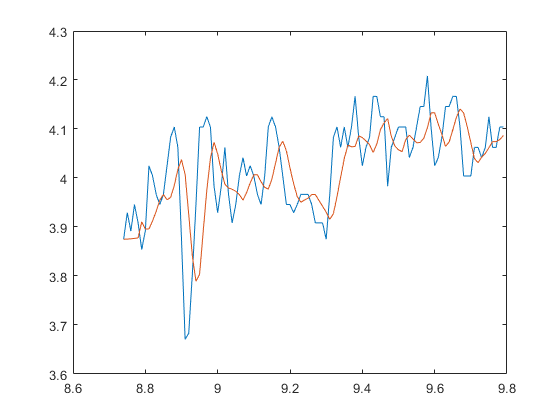

Numescalones=size(datos{NumArchivo}.datos);
Numescalones=Numescalones(3);
NumEscalon=10;
NumMotor=3;
if(NumEscalon>Numescalones)
display(strcat("El Maximo Numero de escalones es : ",num2str(Numescalones)));
else
tiempo=datos{NumArchivo}.datos(1:end-1,1,NumEscalon);
velocidad=datos{NumArchivo}.datos(1:end-1,NumMotor+2,NumEscalon)/240;
plot(tiempo,velocidad);
hold on
velocidad=filtroVelocidad(velocidad,1.5,0.01);
plot(tiempo,velocidad);
hold off
% hold on
% voltaje=str2num(datos{NumArchivo}.voltaje)/100
% voltaje=voltaje*datos{NumArchivo}.datos(:,2,NumEscalon)/10000;
% plot(tiempo,voltaje);
% hold off
end

# Functions

function y=separarEscalones(archivos,carpeta)
    for i=1:length(archivos)
        datos=csvread(strcat(carpeta,archivos(i).name),2);
        title=archivos(i).name;
        Size=size(datos);
        cuenta=0;
        entrada=datos(1,2);
        rangos=[1 1];
        escalon=[];
        for j=1:length(datos)
            if(entrada ~= datos(j,2))
                entrada=datos(j,2);
                cuenta=cuenta+1;
                rangos(1)=rangos(2);
                rangos(2)=j;
                if(cuenta==1)
                    escalon(1:rangos(2)-rangos(1)+1,1:Size(2))=datos(rangos(1):rangos(2),:);
                else
                    escalon(1:rangos(2)-(rangos(1)-3)+1,1:Size(2),cuenta)=datos((rangos(1)-3):rangos(2),:);   
                end
            end
        end
        info_title=strsplit(title(1:length(title)-4),'_');
        a=struct;
        a.datos=escalon;
        a.title=title;
        a.direccion=cellstr(info_title(4));
        a.voltaje=cell2mat(info_title(5));
        a.superficie=cellstr(info_title(3));
        c(i,1)={a};
        
    end
    y=c;
end

function y=filtroVelocidad(velocidad,frecuencia,T)
    filtro=[0,velocidad(1)];
    filtro1=[0,velocidad(1)];
    for i=1:length(velocidad)
        filtro(1)=filtro(2);
        filtro(2)=(2*pi*frecuencia*T*velocidad(i)+filtro(1))/(1+2*pi*frecuencia*T);
        filtro1(1)=filtro1(2);
        filtro1(2)=(2*pi*frecuencia*T*filtro(2)+filtro1(1))/(1+2*pi*frecuencia*T);
        if(i>5)
            velocidad1(i)=(velocidad(i-2)+velocidad(i-1)+velocidad(i-3)+velocidad(i-4)+filtro1(2))/5;
        else
            velocidad1(i)=filtro1(2);
        end
    end
    y=velocidad1;
end